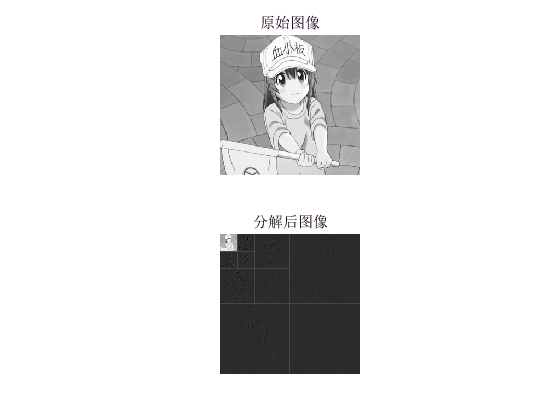

x=imread('G:girl_1.JPEG');
x1=rgb2gray(x);
B= imresize(x1, [256 256]);
subplot(2,1,1);
imshow(B);
title('原始图像');
[c,s]=wavedec2(B,3,'db1');
ch1=detcoef2('h',c,s,1);
cv1=detcoef2('v',c,s,1);
cd1=detcoef2('d',c,s,1);
ch2=detcoef2('h',c,s,2);
cv2=detcoef2('v',c,s,2);
cd2=detcoef2('d',c,s,2);
ca3=appcoef2(c,s,'haar',3);
ch3=detcoef2('h',c,s,3);
cv3=detcoef2('v',c,s,3);
cd3=detcoef2('d',c,s,3);
show1=[ca3,ch3;cv3,cd3];
show2=[show1,ch2;cv2,cd2];
show3=[show2,ch1;cv1,cd1];

[m,n]=size(B);
mm = zeros(m,n);
mm = [show2,ch1;cv1,cd1];
dim = 3;
for i=1:dim
    m=m-mod(m,2);
    n=n-mod(n,2);
    mm(m/2,1:n)=255;
    mm(1:m,n/2)=255;
    m=m/2;
    n=n/2;
end
subplot(2,1,2);
imshow(mm,[]);
title('分解后图像')